Digital Signal Processing Lab (EE-384L)

# Assignment No. 7:   **Transform Analysis of LTI Systems**

### Reg. No. :   **2016-EE-189**

## Task 1

**Statement:**

Consider the LTI system,


$$H\left(z\right)\;=\;\frac{\left(z^{-1} -0\ldotp 9e^{-j\;0\ldotp 2\pi } \right)\left(z^{-1} -0\ldotp 9e^{j\;0\ldotp 2\pi } \right)}{\left(1-0\ldotp 9e^{j\;0\ldotp 2\pi \;} z^{-1} \right)\left(1-0\ldotp 9e^{-j\;0\ldotp 2\pi \;} z^{-1} \right)}$$


and the following input $x\left\lbrack n\right\rbrack$:

$x\left\lbrack n\right\rbrack \;=\;\textrm{sinc}\left(\frac{\pi \left(n-30\right)}{16}\right)\cos \left(\omega_0 \;n\right)$,     $0\le n\le 60$.

**Question (1):**

Plot the magnitude response, phase response (unwrapped), phase response (wrapped/principal value) and group-delay of the system.

How much group-delay is present for signals around frequencies $0\ldotp 2\pi$, $0\ldotp 4\pi$, $0\ldotp 9\pi \;\textrm{radians}/\textrm{sample}$?

**Answer (1):**

The code, along with results (inline), to compute various responses from $H\left(z\right)$ expression above, starts below.

% <task> plot magnitude and phase response of given LTI system

% define z-domain expression (symbolically)
syms z;
Hz_N = (z^-1-0.9*exp(-1i*0.2*pi))*(z^-1-0.9*exp(1i*0.2*pi));        % numerator of H(z)
Hz_D = (1-0.9*exp(1i*0.2*pi)*z^-1)*(1-0.9*exp(-1i*0.2*pi)*z^-1);    % denominator of H(z)
Hz = Hz_N/Hz_D;

% display H(z) expression
disp('H(z) = '); disp(vpa(Hz, 4))

H(z) = 


$$\frac{\left(\frac{1}{z}-0.7281-0.529\,\mathrm{i}\right)\,\left(\frac{1}{z}-0.7281+0.529\,\mathrm{i}\right)}{\left(-1.0+\frac{0.7281-0.529\,\mathrm{i}}{z}\right)\,\left(-1.0+\frac{0.7281+0.529\,\mathrm{i}}{z}\right)}$$

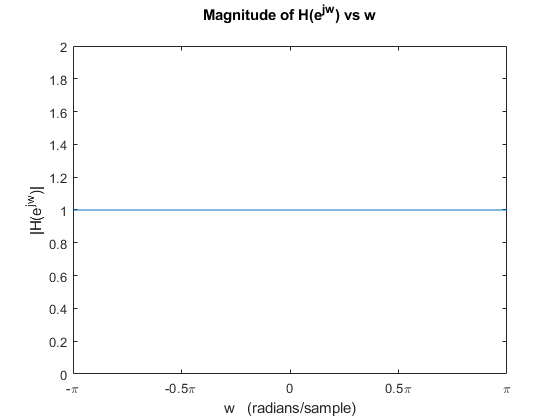


% obtain frequency response H(w) expression from H(z)
% by substituting z = e^(jw)
syms w_;
Hw = subs(Hz, {z}, {exp(1i*w_)});

% compute frequency response H(w) for w = [-pi, pi]
dw = 0.001;
w = -pi:dw:pi;
Hw = subs(Hw, {w_}, {w});
Hw = double(Hw);

% obtain magnitude and phase of H(w)
Hw_mag = abs(Hw);
Hw_arg = phase(Hw);                 % unwrapped phase
Hw_ARG = angle(Hw);                 % wrapped phase
                                    % (in radians)

% plot magnitude of H(w) vs w
fig = figure; 
plot(w, Hw_mag);
xlabel('w   (radians/sample)'); 
ylabel('|H(e^{jw})|'); 
ylim([0 2]);
title({'Magnitude of H(e^{jw}) vs w';''});
setDTFTradialAxis(1);

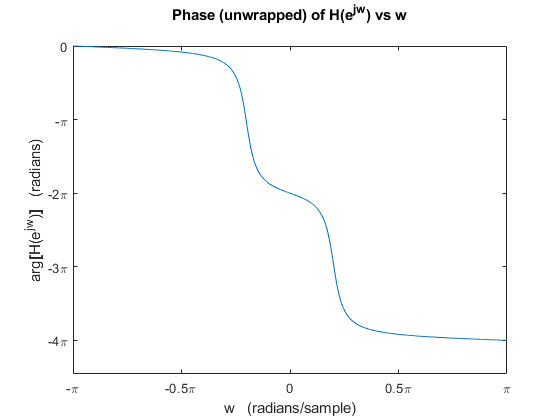


% plot phase (unwrapped) of H(w) vs w
fig = figure; 
plot(w, Hw_arg);
xlabel('w   (radians/sample)'); 
ylabel('arg{\bf[}H(e^{jw}){\bf]}   (radians)');
title({'Phase (unwrapped) of H(e^{jw}) vs w';''});
setDTFTradialAxis(1, 1, 1);

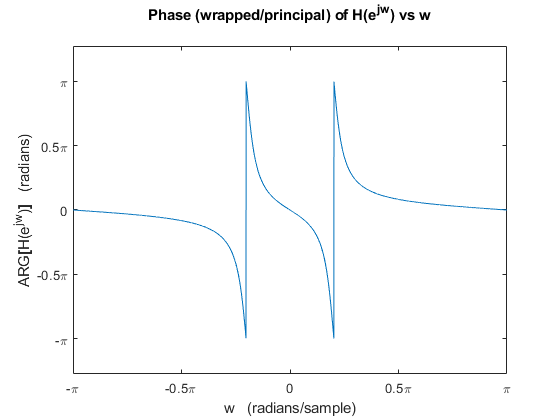


% plot phase (wrapped/principal) of H(w) vs w
fig = figure; 
plot(w, Hw_ARG);
xlabel('w   (radians/sample)'); 
ylabel('ARG{\bf[}H(e^{jw}){\bf]}   (radians)');
title({'Phase (wrapped/principal) of H(e^{jw}) vs w';''});
setDTFTradialAxis(1, 0.5, 1);

Hence, given $H\left(z\right)$ is an All-Pass system of the form ($M_r =0$ & $M_c =1$),


$$H\left(z\right)\;=\;\frac{\left(z^{-1} -e_k^{\;\ast } \right)\left(z^{-1} -e_k \right)}{\left(1-e_k {\;z}^{-1} \right)\left(1-e_k^{\ast } \;z^{-1} \right)}$$


Its magnitude response is a constant ($1$), and because $|e_k |<1$ (where $e_k ={\textrm{re}}^{j\theta }$), it is a causal and stable all-pass system. The unwrapped phase of this causal rational all-pass system is always negative, and so its group-delay will always be positive. Now, the group delay for $H\left(e^{j\omega \;} \right)$ is given by,


$$\tau \left(\omega \right)\;=\;\textrm{grd}\left\lbrack H\left(e^{j\omega } \right)\right\rbrack \;=\;-\frac{d}{d\omega \;}\left\lbrace \arg \left\lbrack H\left(e^{j\omega } \right)\right\rbrack \right\rbrace$$


where the derivative of (unwrapped) phase may be computed using,


$$\frac{d}{d\omega \;}\left\lbrace \arg \left\lbrack H\left(e^{j\omega } \right)\right\rbrack \right\rbrace \;=\;\lim_{\Delta \omega \;\to \;0} \frac{\arg \left\lbrack H\left(e^{j\;\left(\omega \;+\;\Delta \omega \right)} \right)\right\rbrack -\arg \left\lbrack H\left(e^{j\omega } \right)\right\rbrack }{\Delta \omega }$$


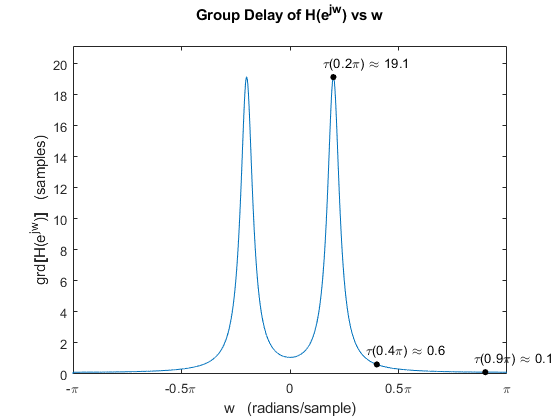


% <task> plot group-delay of given LTI system

dw = (w(end)-w(1))/(length(w)-1);           % compute the w-step-size 'dw' used in w-array

% obtain group-delay of H(w)
Hw_grd = -([Hw_arg 0]-[0 Hw_arg])/dw;
Hw_grd = Hw_grd(1:(length(Hw_grd)-1));

% plot group-delay of H(w) vs w
fig = figure; 
plot(w, Hw_grd);
xlabel('w   (radians/sample)'); ylabel('grd{\bf[}H(e^{jw}){\bf]}   (samples)');
title({'Group Delay of H(e^{jw}) vs w';''});
setDTFTradialAxis(1);

% mark frequencies to be noted on the plot
wvals = [0.2, 0.4, 0.9]*pi;
hold on;
for i = 1:length(wvals)
    yval = Hw_grd(find(w>=wvals(i)-dw & w<=wvals(i)+dw, 1));
    stem(wvals(i), yval, 'k', 'filled', 'LineStyle', 'none', 'MarkerSize', 4);
    text(wvals(i)-0.05*pi, yval+1, ...
        ['\tau(', num2str(wvals(i)/pi), '\pi', ') \approx ', num2str(round(yval, 1))]);
end
ylim([min(Hw_grd) max(Hw_grd)+2])
hold off;

From the datapoints marked in the plot of group-delay above, it can be observed that the group-delay incurred by input signals of mentioned frequencies is about,


$$\begin{array}{l}
\tau \left(\;\;\;0\ldotp 2\pi \;\;\textrm{radians}/\textrm{sample}\;\;\;\right)\;\;\;\;\;\approx \;\;\;\;\;19\ldotp 1\;\;\textrm{samples}\;\textrm{delay}\\
\tau \left(\;\;\;0\ldotp 4\pi \;\;\textrm{radians}/\textrm{sample}\;\;\;\right)\;\;\;\;\;\approx \;\;\;\;\;0\ldotp 6\;\;\textrm{samples}\;\textrm{delay}\\
\tau \left(\;\;\;0\ldotp 9\pi \;\;\textrm{radians}/\textrm{sample}\;\;\;\right)\;\;\;\;\;\approx \;\;\;\;\;0\ldotp 1\;\;\textrm{samples}\;\textrm{delay}
\end{array}$$


**Question (2):**

Draw the spectrum of $x\left\lbrack n\right\rbrack$ for $\omega_0 =0\ldotp 2\pi ,\;0\ldotp 4\pi ,\;0\ldotp 9\pi$.

What is the effect of changing $\omega_0$ on the spectrum of $x\left\lbrack n\right\rbrack$?

**Answer (2):**

Since MATLAB defines $\textrm{sinc}\left(\right)$ function as $\textrm{sinc}\left(x\right)=\frac{\sin \left(\pi x\right)}{\pi x}$, we'll define $x\left\lbrack n\right\rbrack$ as,


$$x\left\lbrack n\right\rbrack =\textrm{sinc}\left(\frac{n-30}{16}\right)\cos \left(\omega_0 n\right)$$


i.e. without the extra $\pi$ in MATLAB. The code, along with the results, to compute & plot the spectrum (DTFT) of given $x\left\lbrack n\right\rbrack$, starts below.

***Note:***  The $\textrm{plotSeqDTFT}\left(\right)$ function used in different tasks has been defined at end of report.

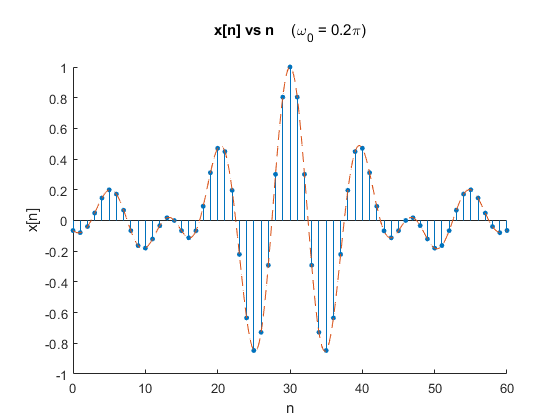

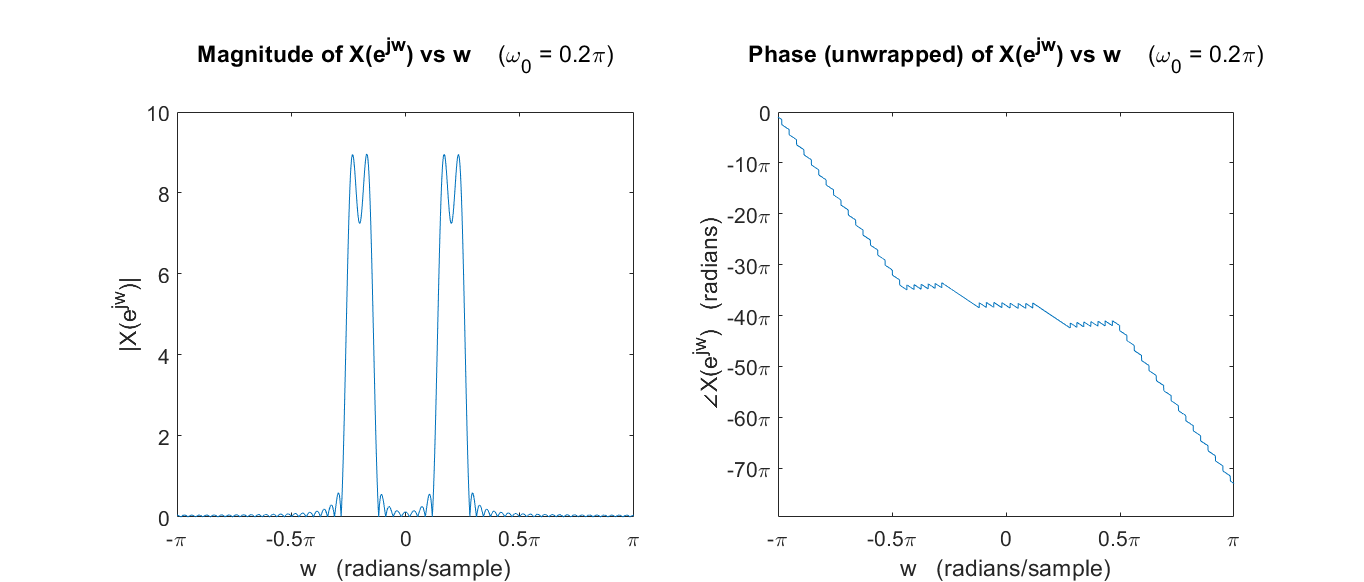

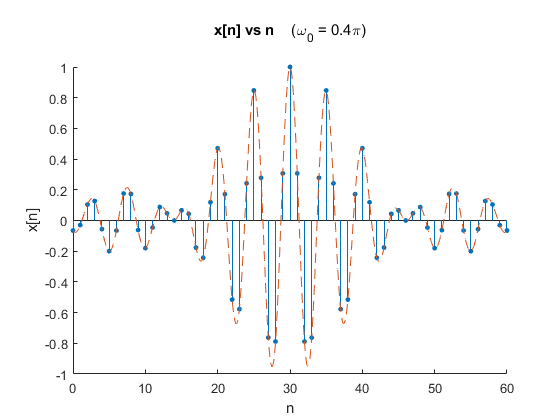

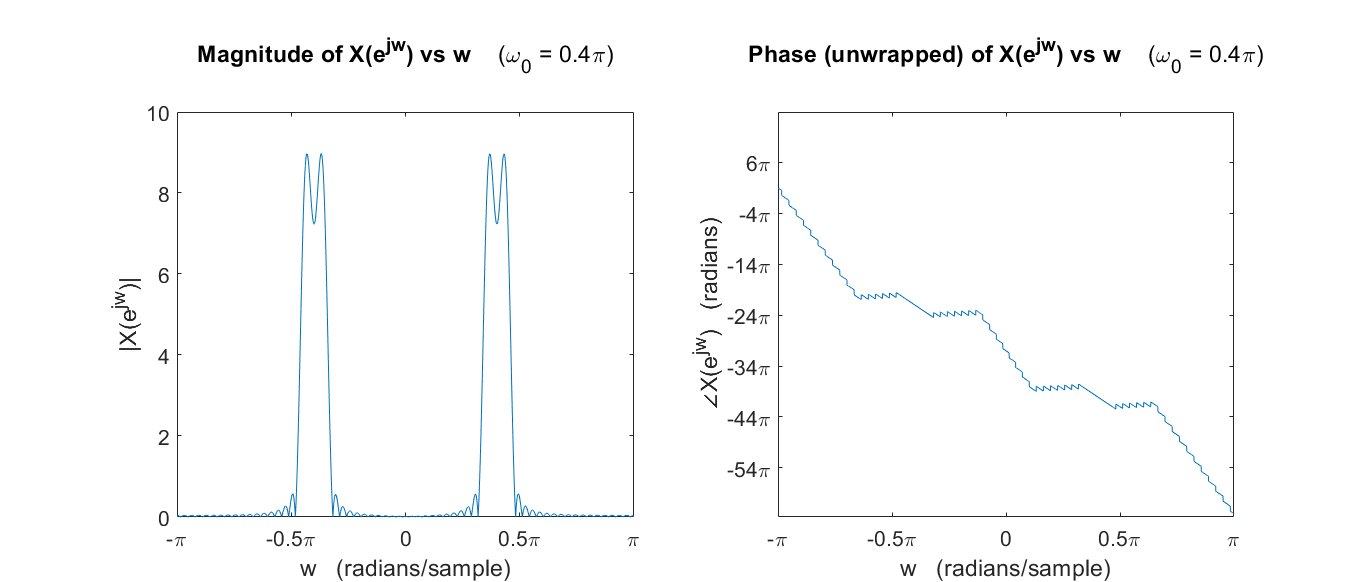

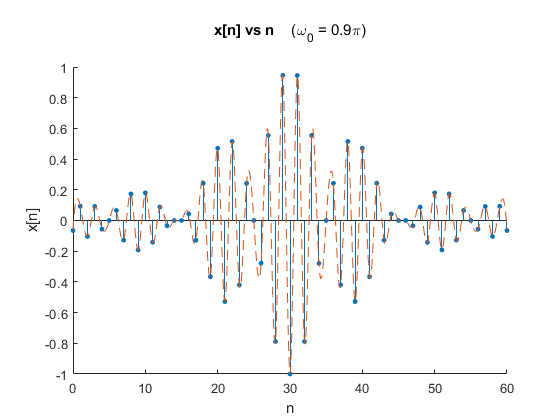

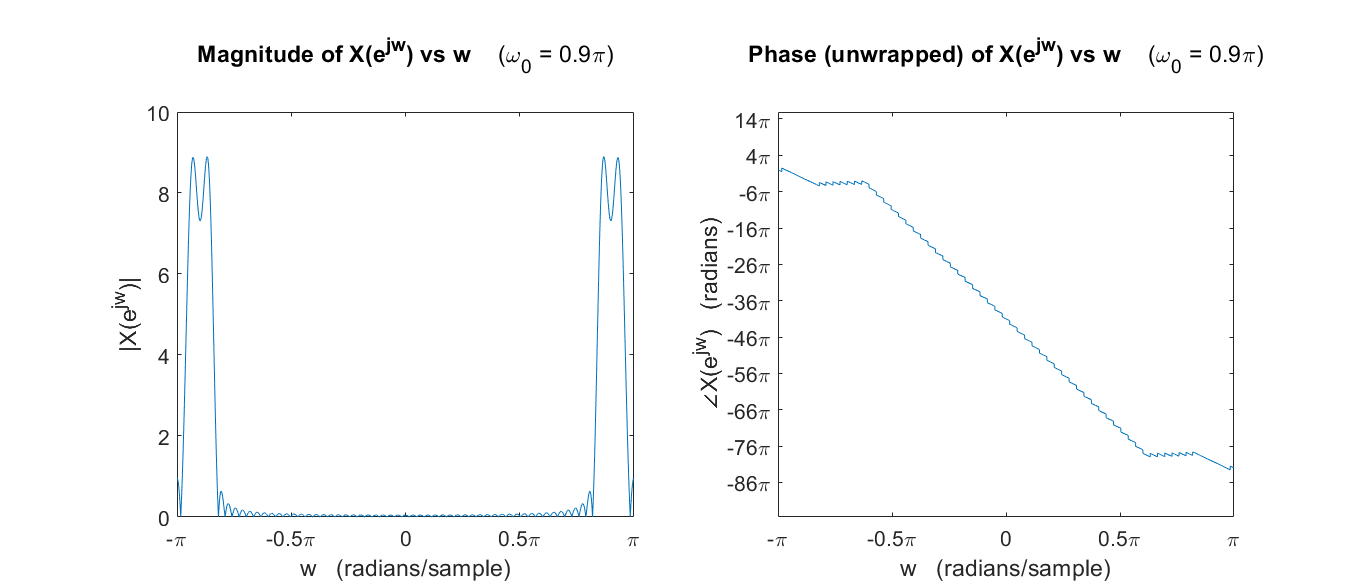

% <task> compute & plot DTFT of given x[n], for each w0 value

w0vals = [0.2, 0.4, 0.9]*pi;
n = 0:60;

for i=1:length(w0vals)
    
    % define x[n] = (sin(pi*(n-30)/16)./(pi*(n-30)/16)).*cos(w0*n)
    w0 = w0vals(i);
    x = sinc((n-30)/16).*cos(w0*n);
    
    % compute DTFT X(w) for current w0
    w = -pi:0.001:pi;                       % for 1 period [-pi, pi] of DTFT
    Xw = x * exp(-1i * n' * w);             % using matrix-multiplication method
    
    % obtain magnitude and phase (unwrapped) of DTFT X(w)
    Xw_mag = abs(Xw);
    Xw_arg = phase(Xw);
    
    % plot sequence x[n] and its DTFT X(w) (magnitude and phase)
    plotSeqDTFT(n, x, w0, w, Xw_mag, Xw_arg, 'x', 'X');
    
end

The expression for $x\left\lbrack n\right\rbrack$ consists of a $\textrm{sinc}\left(\right)$ term multiplied with a $\cos \left(\right)$ term. In the frequency-domain, the $\textrm{sinc}\left(\right)$ function corresponds to a rectangular or gate function centered around $0$. Hence, depending upon the gate's width, it represents a group or collection of frequencies (with roughly same magnitude), until its somewhat-sharp cutoff. The $\cos \left(\right)$ term in $x\left\lbrack n\right\rbrack$ represents impulses in the frequency-domain at exactly $\pm {\;\omega }_0$.

Hence, in the frequency-domain, the gate function of certain width is convolved with impulses, and so the gate is shifted and centered to the location of impulses i.e. at $\pm {\;\omega }_0$. This means that for different $\omega_0$, $x\left\lbrack n\right\rbrack$ represents a different collection of frequencies, albeit the same amount of them.

From analyzing the magnitude plots, the width of each gate-pulse is roughly $0\ldotp 41\;\textrm{rad}/\textrm{sample}$ $\approx 0\ldotp 13\pi \;\textrm{rad}/\textrm{sample}$. It can be observed that as $\omega_0$ is increased, the pulse (+ve & -ve) in the magnitude plots moves towards a higher group of frequencies, and the center of the peaks is at $\pm {\;\omega }_0$ in each case. Hence, given the width of the gate, a rough estimate of the frequencies in each $x\left\lbrack n\right\rbrack$ can be made as follows,


$$\begin{array}{l}
\textrm{for}\;\;\;\omega_0 =0\ldotp 2\pi \;\;\textrm{rad}/\textrm{sample}\;\;\;\;\Longrightarrow \;\;\;\;x\left\lbrack n\right\rbrack \;\textrm{contains}\;\;\;\omega \;\;\approx \;\;\pm \;0\ldotp 135\pi \;\;\;\textrm{to}\;\;\pm 0\ldotp 265\pi \;\;\textrm{rad}/\textrm{sample}\\
\textrm{for}\;\;\;\omega_0 =0\ldotp 4\pi \;\;\textrm{rad}/\textrm{sample}\;\;\;\;\Longrightarrow \;\;\;\;x\left\lbrack n\right\rbrack \;\textrm{contains}\;\;\;\omega \;\;\approx \;\;\pm \;0\ldotp 335\pi \;\;\;\textrm{to}\;\;\pm 0\ldotp 465\pi \;\;\textrm{rad}/\textrm{sample}\\
\textrm{for}\;\;\;\omega_0 =0\ldotp 9\pi \;\;\textrm{rad}/\textrm{sample}\;\;\;\;\Longrightarrow \;\;\;\;x\left\lbrack n\right\rbrack \;\textrm{contains}\;\;\;\omega \;\;\approx \;\;\pm \;0\ldotp 835\pi \;\;\;\textrm{to}\;\;\pm 0\ldotp 965\pi \;\;\textrm{rad}/\textrm{sample}
\end{array}$$


**Question (3):**

Pass $x\left\lbrack n\right\rbrack$ through the system for the three values of $\omega_0$. 

Did you see any change in the signal in the corresponding output? Do you see any change in the signal envelope at the output? Give reason for any change in the output corresponding to the three inputs.

**Answer (3):**

The code, along with the results, to pass $x\left\lbrack n\right\rbrack$ for each $\omega_0$ through $H\left(z\right)$, starts below.

% <task> extract the CCDE coefficients of given system H(z)

disp('H(z) = '); disp(vpa(simplify(Hz), 4));    % display H(z) as a ratio of polynomials

H(z) = 


$$\frac{6.572e+31\,z^{2}-1.181e+32\,z+8.113e+31}{8.113e+31\,z^{2}-1.181e+32\,z+6.572e+31}$$

To use the $H\left(z\right)$ system wtih $x\left\lbrack n\right\rbrack$, we need to first determine its CCDE coefficients. The form of $H\left(z\right)$ above can be used to extract the coefficients directly within MATLAB code, as follows:


% extract b's and a's from H(z) expression
[N, D] = numden(Hz);
b = fliplr(coeffs(N));  a = fliplr(coeffs(D));
b = double(b./a(1));    a = double(a./a(1));
disp('b ='); disp(b);   disp('a ='); disp(a);

b =
    0.8100   -1.4562    1.0000

a =
    1.0000   -1.4562    0.8100



So, $H\left(z\right)$ may be expressed as,


$$\begin{array}{l}
H\left(z\right)\;=\;\frac{0\ldotp 81\,-1\ldotp 4562\,z^{-1} +1\;z^{-2} }{1\,-1\ldotp 4562\,z^{-1} +0\ldotp 81\;z^{-2} }\\
\;\;\;\;\;\;\;\;\;\;\;\;=\;\frac{b_0 {\;z}^0 \,+b_1 \,z^{-1} +b_2 \;z^{-2} }{a_0 \,z^0 +a_1 \,z^{-1} +a_2 \;z^{-2} }
\end{array}$$


where we have,


$$\begin{array}{l}
b\;=\;\left\lbrace \;0\ldotp 81,\;-1\ldotp 4562,\;1\;\right\rbrace \\
a\;=\;\left\lbrace \;1,\;-1\ldotp 4562,\;0\ldotp 81\;\right\rbrace 
\end{array}$$


As a confirmation, the pole-zero plot of $H\left(z\right)$ is plotted below using these coefficients $b$'s and $a$'s.

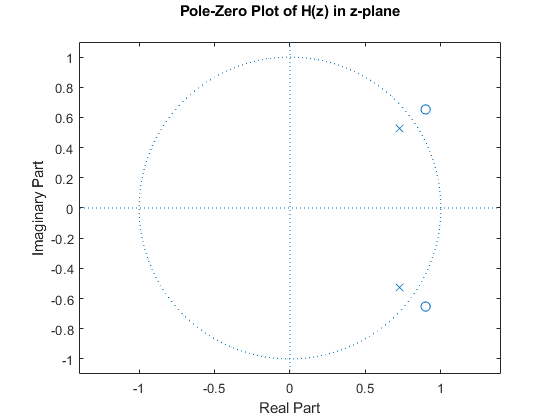


% plot the pole-zero map of H(z)
% using extracted b's and a's
figure;
zplane(b, a);
title({'Pole-Zero Plot of H(z) in z-plane';''});

This plot agrees with the pole-zero form of $H\left(z\right)$ expression given at the start of report, hence the extracted CCDE coefficients are correct.

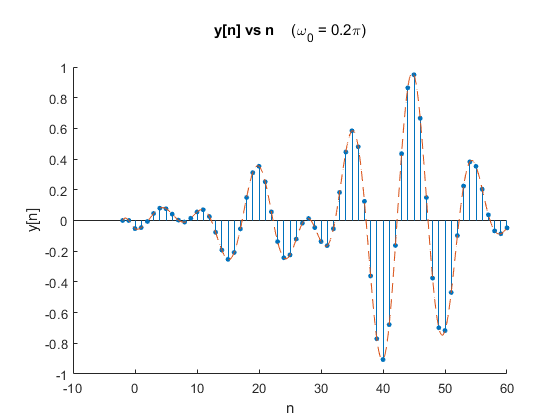

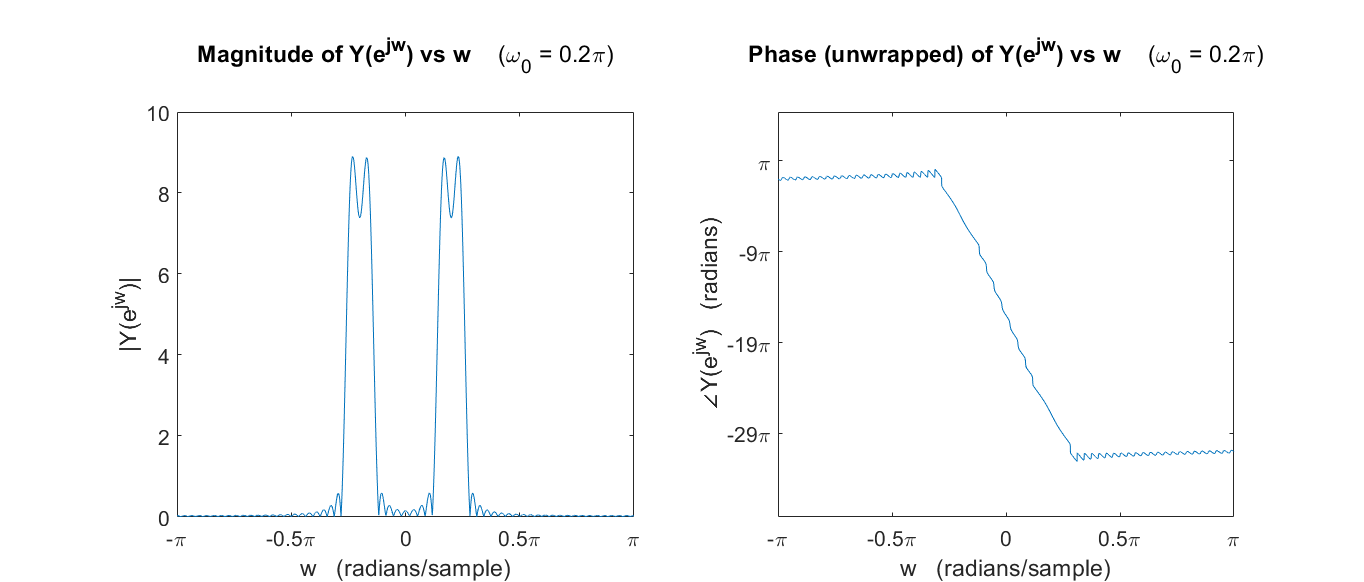

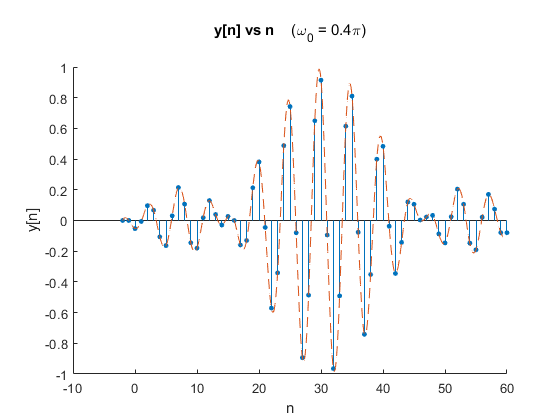

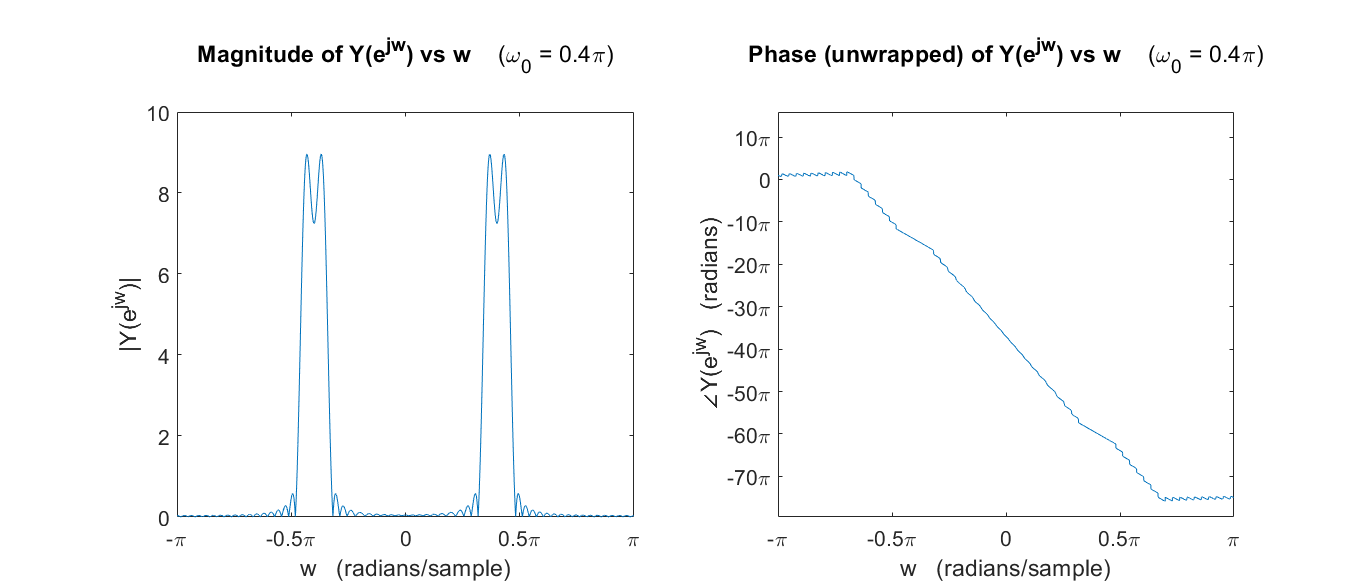

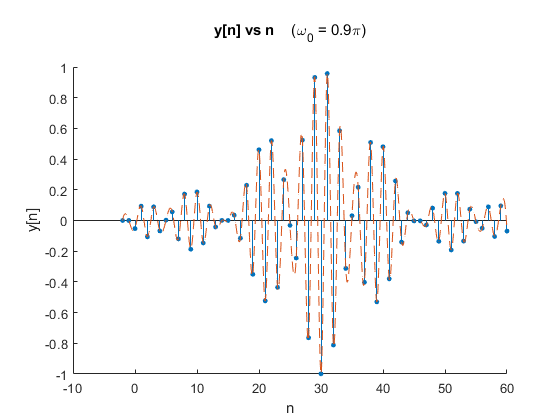

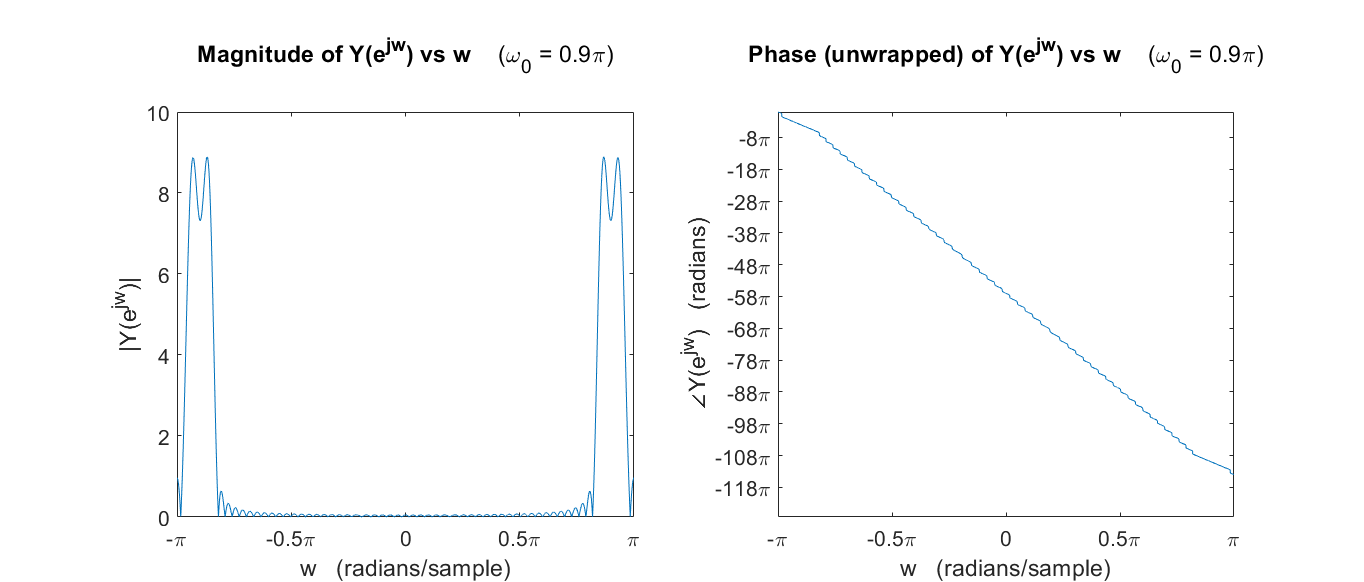

 






Next pagse shows the plots of x[n] against output y[n], for the different values of w0.


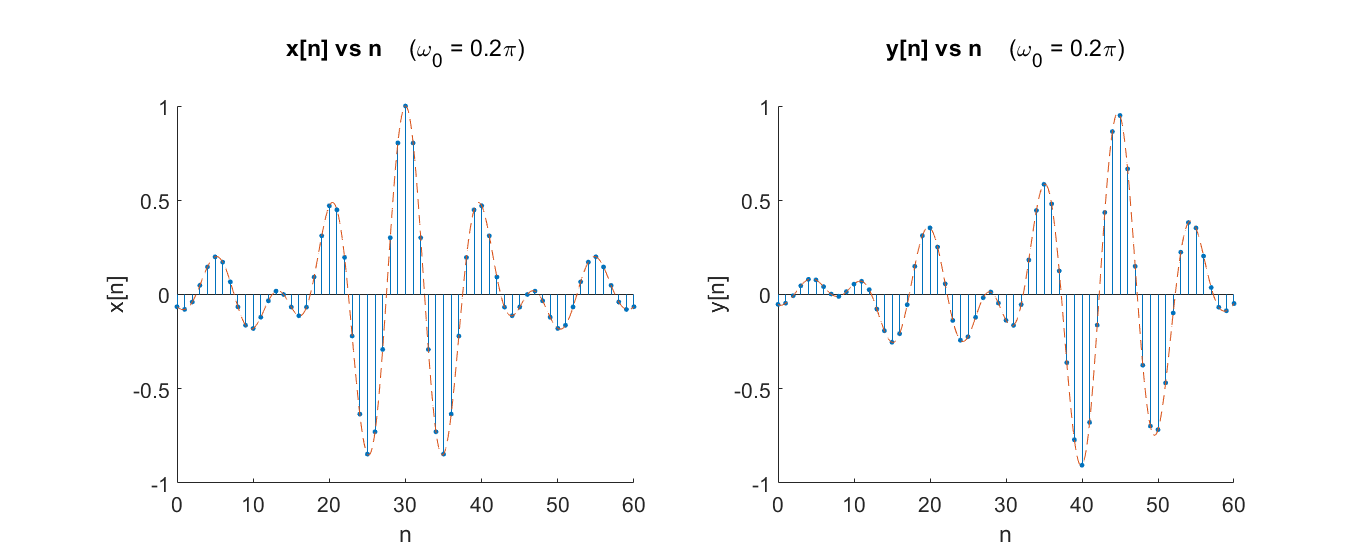

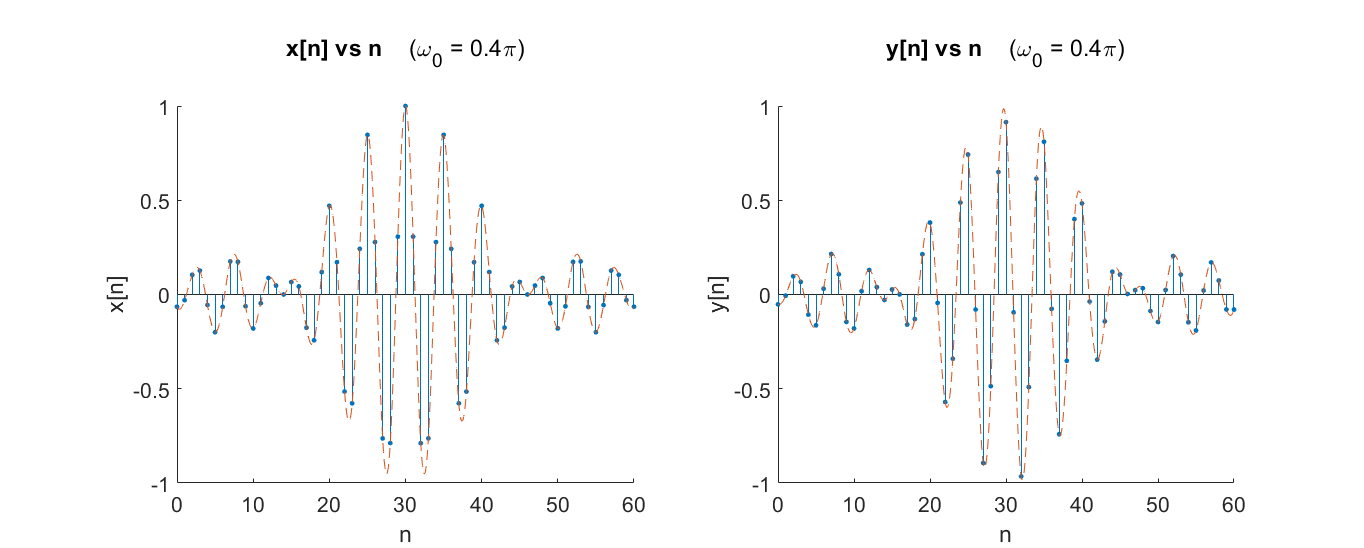

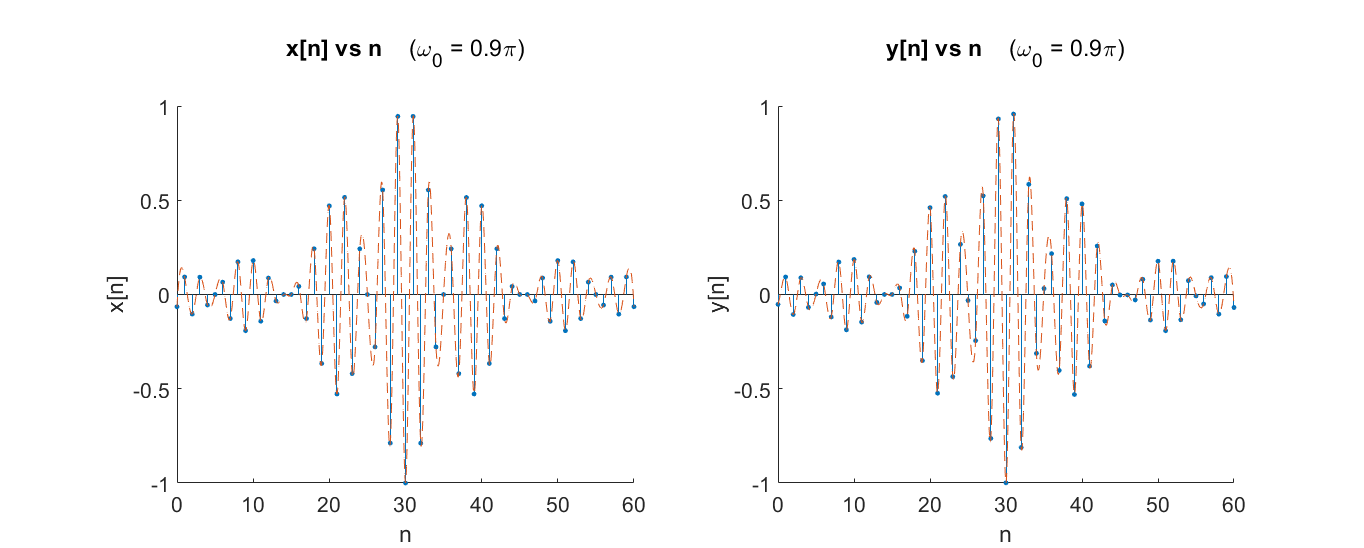


% <task> pass x[n] (for each w0 value) through system H(z),
% and plot the output y[n] and its spectrum

w0vals = [0.2, 0.4, 0.9]*pi;
n = 0:60;
x = cell(1, length(w0vals));                % to store x[n] arrays for different w0
y = cell(1, length(w0vals));                % to store y[n] arrays for different w0
ny = cell(1, length(w0vals));               % to store ny arrays for different w0

for i=1:length(w0vals)
    
    % define x[n] = (sin(pi*(n-30)/16)./(pi*(n-30)/16)).*cos(w0*n)
    w0 = w0vals(i);
    x{i} = sinc((n-30)/16).*cos(w0*n);
    
    % assuming zero initial conditions (rest)
    N_aux = zeros(1, length(a)-1);
    M_init = zeros(1, length(b)-1);
    
    % compute output y[n], with input x[n] to system represented by H(z),
    % using get_system_out() and extracted b's and a's
    [y{i}, ny{i}] = get_system_out(b, a, x{i}, N_aux, M_init);
    
    % compute DTFT Y(w)
    w = -pi:0.001:pi;                       % for 1 period [-pi, pi] of DTFT
    Yw = y{i} * exp(-1i * ny{i}' * w);      % using matrix-multiplication method
    
    % obtain the magnitude of DTFT Y(w)
    Yw_mag = abs(Yw);
    
    % obtain the phase (unwrapped, in radians) of DTFT Y(w)
    Yw_arg = phase(Yw);
    
    % plot resultant sequence y[n], and its DTFT Y(w) (magnitude and phase)
    plotSeqDTFT(ny{i}, y{i}, w0, w, Yw_mag, Yw_arg, 'y', 'Y');
    
    if i == length(w0vals)
        disp([' ', newline, newline, newline, newline, newline, newline, newline, ... 
            'Next pagse shows the plots of x[n] against output y[n], ' ...
            'for the different values of w0.']);
        
        % plot side-by-side plots of x[n] & y[n] for different w0
        for k = 1:length(w0vals)
            plotSeqDTFT(ny{k}, y{k}, w0vals(k), [], [], [], 'y', '', n, x{k}, 'x', 1);
        end
    end
    
end

The plots show the input $x\left\lbrack n\right\rbrack$ and output $y\left\lbrack n\right\rbrack$ sequences side by side (Page 16), and the DTFT of $y\left\lbrack n\right\rbrack$ (Pages 13, 14, and 15) for various $\omega_0$ values.

Firstly, the magnitude plots of $Y\left(e^{j\omega } \right)$ show that system has not distorted the magnitude of different frequencies, compared to magnitude of $X\left(e^{j\omega } \right)$. This is because the system is an All-Pass system, and has magnitude $|H\left(e^{j\omega } \right)|=1$ $\forall \;\omega$. As a result, the envelope (or shape) of $y\left\lbrack n\right\rbrack$ (roughly) matches with that of $x\left\lbrack n\right\rbrack$, apart from the visible phase-shift introduced in $y\left\lbrack n\right\rbrack$.

Although given system $H\left(z\right)$ does not distort magnitude, it still distorts the phase of the input signal, as apparent from the phase plot $\arg \left\lbrack H\left(e^{j\omega } \right)\right\rbrack$ in Q1. The group-delay $\textrm{grd}\left\lbrack H\left(e^{j\omega } \right)\right\rbrack$ or $\tau \left(\omega \right)$ plot, shown in Q1, gives an estimate of this phase-shift introduced to different input frequencies. Its y-axis tells the number of samples by which some frequency on the x-axis is shifted. Now since $H\left(z\right)$ has all its poles inside the unit circle, and the unit circle is in ROC, it is a stable & causal all-pass system — with the property that its group-delay is positive $\forall \;\omega$. Hence, the various groups of frequencies in each $x\left\lbrack n\right\rbrack$, centered respectively at $\omega =\omega_0 =0\ldotp 2\pi ,\;0\ldotp 4\pi ,\;0\ldotp 9\pi \;\mathrm{rad}/\mathrm{sample}$, will incur *delays* (+ve shifts) of samples, albeit by different amounts indicated by the group-delay plot.

$x\left\lbrack n\right\rbrack$ for a given $\omega_0$ has a number of frequecies in it, centered around $\omega_0$, as described in Q2. This means that the different frequencies in this group will be delayed by different number of samples. This would somewhat distort the shape of output $y\left\lbrack n\right\rbrack$, but not largely since frequency-group lies in a continuous smooth region of the group-delay curve. So we may still determine a rough amount of overall delay in $y\left\lbrack n\right\rbrack$ compared to $x\left\lbrack n\right\rbrack$, by inspecting the sequence plots above,


$$\begin{array}{l}
\mathrm{for}\;\;\;\omega_0 =0\ldotp 2\pi \;\;\mathrm{rad}/\mathrm{sample}\;\;\;\;\Longrightarrow \;\;\;y\left\lbrack n\right\rbrack \;\mathrm{is}\;\mathrm{delayed}\;\mathrm{by}\;\mathrm{about}\;\;\approx \;17\;\;\mathrm{samples}\\
\mathrm{for}\;\;\;\omega_0 =0\ldotp 4\pi \;\;\mathrm{rad}/\mathrm{sample}\;\;\;\;\Longrightarrow \;\;\;y\left\lbrack n\right\rbrack \;\mathrm{is}\;\mathrm{delayed}\;\mathrm{by}\;\mathrm{about}\;\;\approx \;1\;\;\mathrm{sample}\\
\mathrm{for}\;\;\;\omega_0 =0\ldotp 9\pi \;\;\mathrm{rad}/\mathrm{sample}\;\;\;\;\Longrightarrow \;\;\;y\left\lbrack n\right\rbrack \;\mathrm{not}\;\mathrm{delayed}\;\mathrm{by}\;\mathrm{any}\;\mathrm{noticable}\;\mathrm{amount}
\end{array}$$


compared to $x\left\lbrack n\right\rbrack$. This agrees with the group-delays noted for the center-frequencies $\omega_0 =0\ldotp 2\pi ,\;0\ldotp 4\pi ,\;0\ldotp 9\pi$ $\mathrm{rad}/\mathrm{sample}$ in Q1, that is, input with frequency around $0\ldotp 2\pi \;\textrm{rad}/\textrm{sample}$ incurs a large delay ($\approx 19\;\textrm{samples}$), frequency around $0\ldotp 4\pi \;\textrm{rad}/\textrm{sample}$ incurs a very small delay ($\approx 1\;\mathrm{sample}$), and frequency around $0\ldotp 9\pi \;\textrm{rad}/\textrm{sample}$ incurs negligible delay ($\approx 0\;\mathrm{samples}$).

Thus, in summary, the frequency content of input remains unchanged, the shape of input is (very slightly) distorted due to different delays in different frequencies of the group, and the overall signal is delayed by (on average) some number of samples — with the amount of samples of delay decreasing onwards from $\omega =0\ldotp 2\pi \;\mathrm{rad}/\mathrm{sample}$.

*Functions used the the tasks are provided starting on the next page.*

## Functions used in the tasks

### plotSeqDTFT()

Used in Task 1 (Q2, Q3) — to plot given sequence against $n$-values, and its magnitude and phase response against $\omega$-values.

% <function> 
% plots given sequence against given n values and its given DTFT 
% (magnitude and phase response) against given w values.
%
% <syntax>
% plotSeqDTFT(n, x, w0, w, Xw_mag, Xw_arg, Nn, Nw, <n1>, <x1>, <Nn1>, <skipDTFTplot>)
%
% <I/O>
% x = sequence x[n] array
% w0 = center frequency of x[n]
% w = DT frequencies array [-pi, pi]
% Xw_mag = DTFT magnitude
% Xw_arg = DTFT phase (unwrapped)
% Nn = name of sequence for label/title in plot
% Nw = name of DTFT for label/title in plot
% x1 = optional second sequence x1[n1] to plot against x[n]
% Nn1 = name of optional second sequence
% skipDTFTplot = boolean to indicate whether to skip plotting DTFT

function plotSeqDTFT(n, x, w0, w, Xw_mag, Xw_arg, Nn, Nw, n1, x1, Nn1, skipDTFTplot)
    
    % default is to plot DTFT (not skip)
    if ~(nargin == 12); skipDTFTplot = 0; end
    
    if nargin >= 11
        % plot first sequence x1[n1] for comparison
        fig = figure; set(fig,'Units','normalized','Position',[0 0 1.4 1]);
        subplot(1, 2, 1);
        hold on;
            stem(n1, x1, 'filled', 'MarkerSize', 3);
            n2 = min(n1):1/1000:max(n1);
            plot(n2, interp1(n1,x1,n2,'spline'), '--');
        hold off;
        xlabel('n'); ylabel([Nn1, '[n]']);
        title({'';['{\bf', Nn1, '[n] vs n}', '    (\omega_0 = ', ...
            num2str(w0/pi), '\pi)'];''}, 'FontSize', 16, 'FontWeight', 'normal');
        ax = gca; ax.FontSize = 16;
        subplot(1, 2, 2);
    else
        figure;
    end
    
    % plot x[n] vs n
    hold on;
        stem(n, x, 'filled', 'MarkerSize', 3);
        n2 = min(n):1/1000:max(n);
        plot(n2, interp1(n,x,n2,'spline'), '--');
    hold off;
    xlabel('n'); ylabel([Nn, '[n]']);
    if nargin >= 11
        xlim([min(n1) max(n1)]);
        title({'';['{\bf', Nn, '[n] vs n}', '    (\omega_0 = ', ...
            num2str(w0/pi), '\pi)'];''}, 'FontSize', 16, 'FontWeight', 'normal');
        ax = gca; ax.FontSize = 16;
    else
        title({'';['{\bf', Nn, '[n] vs n}', '    (\omega_0 = ', ...
            num2str(w0/pi), '\pi)'];''}, 'FontWeight', 'normal'); 
    end
    
    if ~skipDTFTplot
        % plot magnitude and phase of DTFT X(w) vs w
        fig = figure; set(fig,'Units','normalized','Position',[0 0 1.45 1.1]);
        subplot(1, 2, 1);
        plot(w, Xw_mag);
        xlabel('w   (radians/sample)'); ylabel(['|', Nw, '(e^{jw})|']);
        title({'';['{\bfMagnitude of ', Nw, '(e^{jw}) vs w}', '    (\omega_0 = ', ...
            num2str(w0/pi), '\pi)'];''}, 'FontSize', 16, 'FontWeight','normal');
        setDTFTradialAxis(1); 
        ax = gca; ax.FontSize = 16;
        subplot(1, 2, 2);
        plot(w, Xw_arg);
        xlabel('w   (radians/sample)'); ylabel(['∠', Nw, '(e^{jw})   (radians)']);
        title({'';['{\bfPhase (unwrapped) of ', Nw, ...
            '(e^{jw}) vs w}', '    (\omega_0 = ', num2str(w0/pi), '\pi)'];''}, ...
            'FontSize', 16, 'FontWeight','normal');
        setDTFTradialAxis(1, 10, 1); 
        ax = gca; ax.FontSize = 16;
    end
    
end

;